Casadi solver test

Scenario: coasting with vx = 10m/s, with tracking cost function.

Cost function: 

sum((obj.vx - obj.vxRef).^2) +sum((obj.vy - obj.vyRef).^2) +sum((obj.py - obj.pyRef).^2)

Control constraint: [-5, 5] (rad/s),    [-1000,1000] (Nm)

Initial constraint: exact

Path constraint: n/a

Terminal constraint: n/a

Solver initialization: all zero except vx = 10, omega_f = omega_r = 30, px = linspace(0,max)

LESSON LEARNED:

making the tire model more smooth (differentiable) really makes the difference.

addpath('C:\Program Files\casadi-windows-matlabR2016a-v3.5.5');
import casadi.*
% MPC subproblem settings
T = 0.5;    % seconds
N = 20;     % number of control intervals

clear sol;
OCP = vehOCP(N,T);
OCP.build_basics();
OCP.add_reference();    % default reference: vx = 10, vy = 0, py = 0.
OCP.tracking_objective();

Tracking objective added!


OCP.add_control_bounds(); % use default bounds
v_xb0 = 10; v_yb0 = 0; px0 = 0; py0 = 0; r0 = 0; psi0 = 0; omega_f0 = 30; omega_r0 = 30; delta0 = 0;
OCP.add_initial_conditions(v_xb0,v_yb0,px0,py0,r0,psi0,omega_f0,omega_r0,delta0); % driving straight
OCP.add_ego_centers();
OCP.set_solver_init(10, 0, 0, 0, 0, 0, 30, 30, 0);  % vx,vy,px,py,r,psi,wf,wr,delta
px0_array = linspace(0,T*v_xb0, N+1);
OCP.opti.set_initial(OCP.px,px0_array); % initialize px with a linear array
% solver_opts = struct('max_iter',500);
plugin_opts = struct('print_time',true);
solver_opts = struct('max_iter',500,'hessian_approximation','limited-memory','tol',1e-3);
% try
    %sol = OCP.solve(plugin_opts,solver_opts);
    fval = OCP.fmincon_solve();

objective computed
Elapsed time is 0.001470 seconds.
constraints computed
Elapsed time is 0.011102 seconds.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    0.000000e+00     4.077e-01     1.000e+00     0.000e+00     0.000e+00  
objective computed
Elapsed time is 0.000879 seconds.
constraints computed
Elapsed time is 0.011708 seconds.
objective computed
Elapsed time is 0.000515 seconds.
constraints computed
Elapsed time is 0.012454 seconds.
    1           3    5.396328e-02     2.864e-03     1.000e+00     6.759e-01     2.166e-01  
objective computed
Elapsed time is 0.000847 seconds.
constraints computed
Elapsed time is 0.012215 seconds.
objective computed
Elapsed time is 0.000501 seconds.
constraints computed
Elapsed time is 0.011660 seconds.
    2           5    5.181793e-02     3.364e-06     1.000e+00     4.856e-02     1.110e-02  
ob

    %OCP.fmincon_plot();
% catch
%     disp("Solution Not Found.");
% end

if ~exist('sol','var')
    foundSol = false
    sol = OCP.opti.debug;
else
    foundSol = true
end

foundSol = logical
   0


If the solver has a solution, we can visualize the states, intermediate variables, controls.

If the solver failed, we can still use opti.debug.value() to investigate the values of variables.

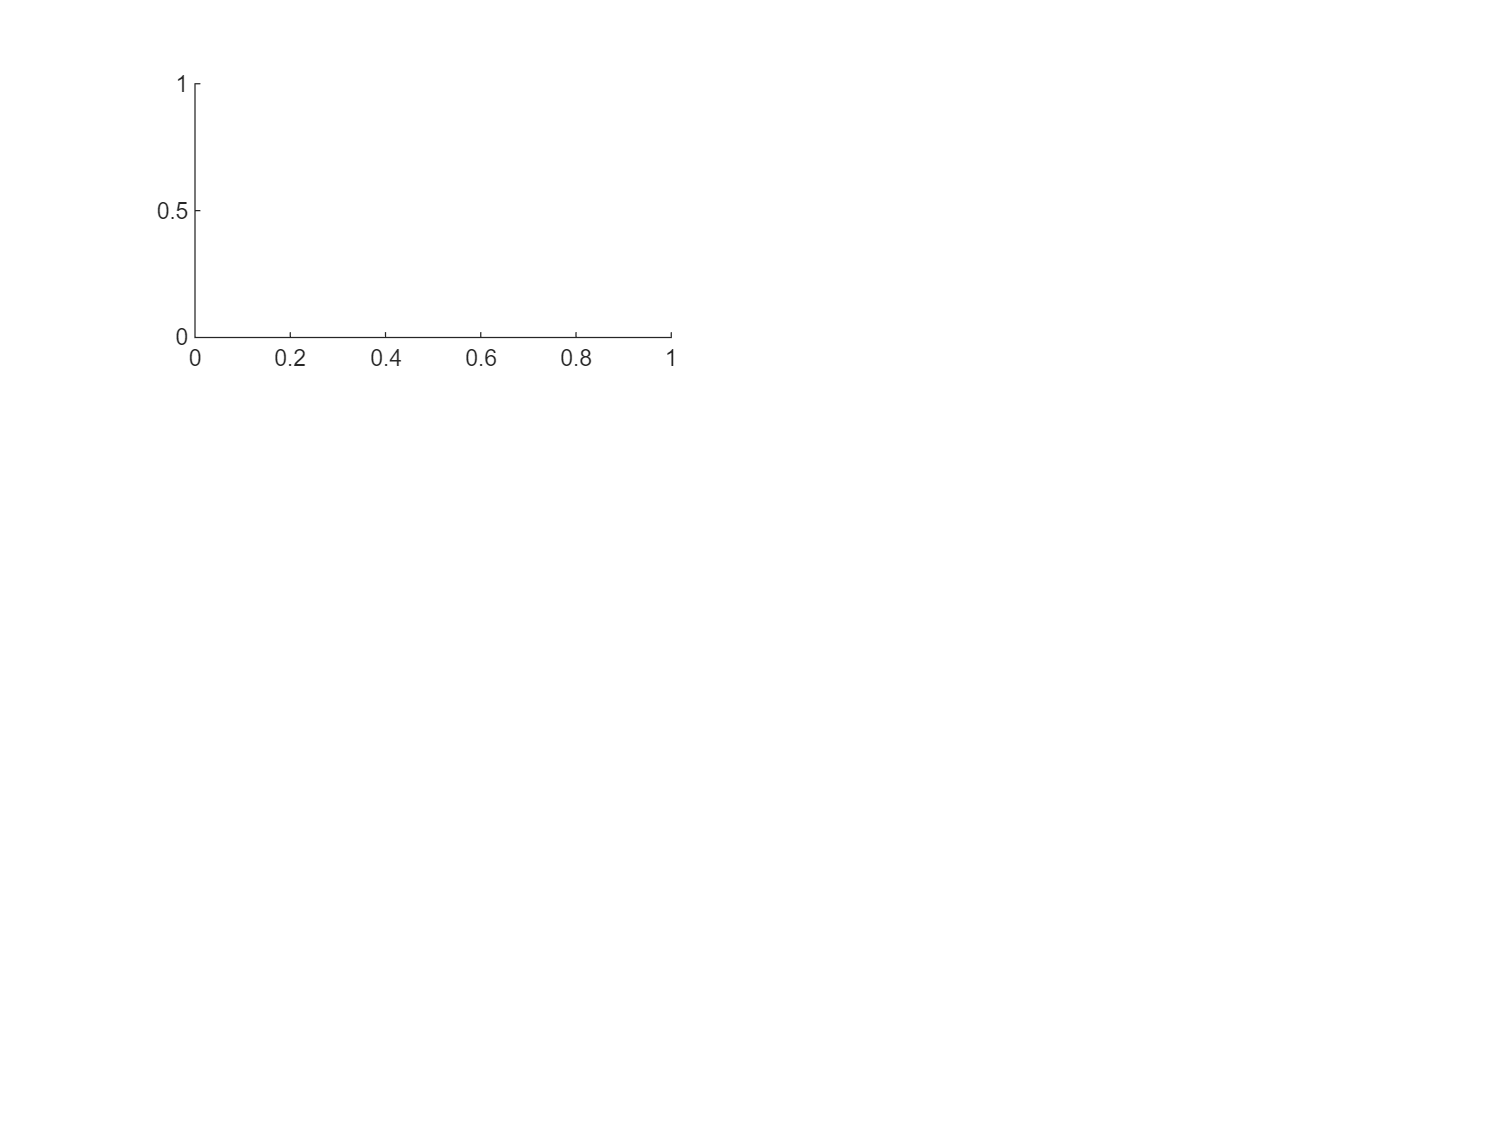

Error using casadi.Opti/value
Error in Opti::value [OptiNode] at
.../casadi/core/optistack.cpp:175:
.../casadi/core/optistack_internal.cpp:872: Assertion
"solved()" failed:
This action is forbidden since you have not solved the Opti
stack yet (with calling 'solve').

Error in pp.basic_plots_dugoff (line 194)
            plot(sol.value(OCP.vx),'LineWidth',2);

% if solutin is found, set foundSol = true. Otherwise set foundSol = false, and 
% the debug results will be used instead.
% [cost, cost_vx, cost_vy, cost_py] = pp.calculate_cost(OCP,sol,foundSol)
pp.basic_plots_dugoff(OCP,sol);

pp.controls_plot_dugoff(OCP,sol)
% pp.debug_plot(OCP,sol,foundSol)

pp.rectangle_overlap(OCP,sol);

Use the 3-circle representation:

pp.circles_overlap(OCP,sol);

Check constraint violations (cv)

cv_control_bounds = dbg.control_bounds_violation(sol, OCP, 5, 1000)
cv_initial_constraints = dbg.initial_constraints_violation(sol, OCP, v_xb0,v_yb0,px0,py0,r0,psi0,omega_f0,omega_r0,delta0)
cv_path_constraints = dbg.path_constraints_violation(sol,OCP,px0,py0,5,2)
% cv_collision_violation = dbg.collision_constraints_violation(sol,OCP)
cv_dynamic_constraints = dbg.dynamic_constraints_violation(sol, OCP)

Animation

pp.make_video_rectangles(OCP,sol,'video',foundSol);